# Bayesian VAR modeling in MATLAB

# New features in Econometrics - MATLAB

## Interactive workflows for multivariate models

The [**Econometric Modeler**](https://www.mathworks.com/help/econ/econometricmodeler-app.html) app enables you to test multiple time series for cointegration among the variables by performing the Engle-Granger cointegration test or the Johansen cointegration test.

After assessing the cointegrating relationships among the series, you can fit vector autoregression (VAR) models, including optional exogenous variables (VARX) or vector error-correction (VEC) models. As with univariate models, after working in the app, you can export variables to the MATLAB® workspace and generate code or a report summarizing your session. For more details, [Econometric Modeler App Overview](https://www.mathworks.com/help/econ/econometric-modeler-overview.html).

## Bayesian VAR models

Econometrics Toolbox™ provides Bayesian vector autoregression (VAR) models for analyzing multivariate time series data from a Bayesian point of view. The [`bayesvarm`](https://www.mathworks.com/help/releases/R2020a/econ/bayesvarm.html) function creates a Bayesian VAR model object that characterizes the joint prior distribution on the coefficients and innovations covariance matrix. The framework enables you to regularize coefficients by using the Minnesota prior [[124]](https://www.mathworks.com/help/releases/R2020a/econ/bibliography.html#mw_e4462390-8552-40d7-b2b1-3f07501788b7). This table lists supported prior models, ordered by increasing flexibility and complexity.

[`normalbvarm`](https://www.mathworks.com/help/releases/R2020a/econ/normalbvarm.html)

- Normal model

- Normal coefficients; fixed innovations covariance matrix

[`conjugatebvarm`](https://www.mathworks.com/help/releases/R2020a/econ/conjugatebvarm.html)

- Conjugate matrix-normal-inverse-Wishart model

- Dependent coefficients and innovations covariance matrix

[`semiconjugatebvarm`](https://www.mathworks.com/help/releases/R2020a/econ/semiconjugatebvarm.html)

- Semiconjugate normal-inverse-Wishart model

- Independent coefficients and innovations covariance matrix

[`diffusebvarm`](https://www.mathworks.com/help/releases/R2020a/econ/diffusebvarm.html)

- Diffuse model

- Joint prior distribution is inversely proportional to the determinant of the innovations covariance matrix

## Bayesian State Spate Models

A new Bayesian state-space models for analyzing multivariate time series data from a Bayesian point of view. The [`bssm`](https://www.mathworks.com/help/econ/bssm.html) function creates a Bayesian state-space model (`bssm` object) that characterizes the joint prior distribution on the state and observation equation parameters, including coefficient, state-disturbance-loading, and observation-innovation matrices.

The framework enables you to create a Bayesian state-space model in two ways:

- Convert a standard state-space model ([`ssm`](https://www.mathworks.com/help/econ/ssm-class.html) object) to a Bayesian state-space model by using the [`ssm2bssm`](https://www.mathworks.com/help/econ/ssm2bssm.html) function.

- For maximum flexibility, pass the following inputs to `bssm`: (1) A parameter-to-matrix mapping function that specifies the structure of the state-space model and determines the likelihood computed by the Kalman filter (2) A prior distribution of the parameters, a function representing the log prior or matrix of random draws from the distribution

After creating a Bayesian state-space model, you can combine the prior model with data to form and analyze the posterior distribution. The data likelihood is formed by assuming that the state disturbances and observation innovations are multivariate Gaussian random variables with a mean of 0. The posterior distribution does not have a closed form; the framework uses Metropolis-Hastings to sample from the posterior. Posterior distribution formation and analysis functions include:

- [`estimate`](https://www.mathworks.com/help/econ/bssm.estimate.html) – Estimate moments of the posterior distribution given the state-space model structure, data, and initial values for optimization.

- [`simulate`](https://www.mathworks.com/help/econ/bssm.simulate.html) – Draw random state-space model parameters for custom Monte Carlo estimation.

- [`tune`](https://www.mathworks.com/help/econ/bssm.tune.html) – Compute proposal distributions for the Metropolis-Hasting sampler to facilitate Monte Carlo simulation.

# BVAR models

Bayesian VAR (BVAR) models have the same mathematical form as any other **VAR model**, i.e.


$$y_t=c+\sum_{l=i}^pA_iy_{t-i}+\epsilon_t$$


where $y_t$ is a $K\times 1$ vector of endogenous variables in period $t$, $A_i$ is the cofficient matrix corresponding to the $i^{th}$ lag of $y_t$, $c$ is a constant deterministic term and $\epsilon$ is an error term with zero mean and variance-covariance $\Sigma$.

The only difference between usual VAR models and BVAR models is the way parameter estimates are obtained and interpreted. VAR models are usually estimated by OLS (ordinary least squares), which is a simple and computationally fast estimator. By contrast, Bayesian estimators are slightly more complicated and more burdensome in terms of algebra and calculation power. The coefficients obtained by so-called *frequentist* estimators like OLS are interpreted based on the concept of the [**sampling distribution**](https://en.wikipedia.org/wiki/Sampling_distribution). In Bayesian inference, the coefficients are assumed to have their own distribution. A more detailed treatment of the difference between frequentist and Bayesian inference can be found in Kennedy (2008, ch. 14), which provides a short introduction to the Bayesian approach and a series of references for interested readers. Koop and Korobilis (2010) provide a very good introduction to Bayesian VAR estimators.

**Prior distributrion**

$\pi({\bf A})$:  distribution of the parameters of the VAR model based on the observed frequency of a sample.

**Posterior distribution**

$\pi({\bf A} | {\bf y})$: distribution of the parameters of the VAR model based on the observed frequency of the sample

**Bayes theorem**


$$\pi(A | {\bf y}) = \frac{\pi({\bf y}| {\bf A}) \pi({\bf y})}{\pi({\bf A})}$$


As already mentioned, Bayesian inference can be algebraically demanding. However, Bayesian estimators for linear VAR models can be implemented in a straightforward manner. A standard implementation is a so-called **Gibbs sampler**, which belongs to the family of Markov-Chain-Monte-Carlo (MCMC) methods. A detailed treatment of this method is beyond the scope of this document, but [**Wikipedia**](https://en.wikipedia.org/wiki/Gibbs_sampling) might be a good start to become familiar with it. Personally, I like to think of the Gibbs sampler as throwing a bunch of random numbers at a model and see what sticks. The remainer of this text provides the code to set up and estimate a basic BVAR model with MATLAB.

## Monetary Policy in a Trivariate VAR

Let's consider a model for studying monetary policies involving three macroeconomic variables: the inflation rate, the unemployment rate and the interest rate, which are assumed to follow a vector autoregression (VAR) process. We could interpret the unexpected change of the interest rate as the monetary policy shock. This model is studied by Cogley and Sargent (2005), Primiceri (2005) and Koop and Korobilis (2009), among others.

Our bash tasks closely follow the empirical illustration of Bayesian VAR in [Koop and Korobilis (2010)](http://personal.strath.ac.uk/gary.koop/kk3.pdf).

To illustrate Bayesian VAR methods using some of the priors and methods described above, we use a quarterly US data set on the inflation rate $\Delta \pi_t$ (the annual percentage change in a chain-weighted GDP price index), the unemployment rate $u_t$ (seasonally adjusted civilian unemployment rate, all workers over age 16) and the interest rate $r_t$ (yield on the three month Treasury bill rate). Thus $y_t = (\Delta\pi_t, u_t, r_t)'$. The sample runs from 1953Q1 to 2006Q3. These three variables are commonly used in New Keynesian VARs.

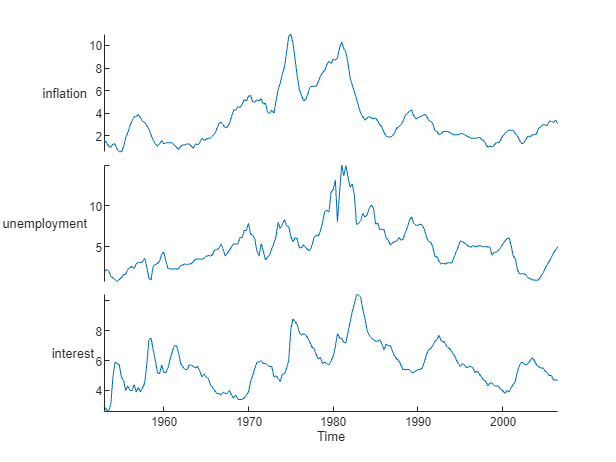

clear;

c = fred('https://research.stlouisfed.org/fred2');
c.DatetimeType = 'datetime';
c.DataReturnFormat = 'timetable';

startdate = datetime(1953,1,1);
enddate = datetime(2006, 7, 1);

inflation    = c.fetch('B191RO1Q156NBEA', startdate , enddate );
inflation = inflation.Data{1};
unemployment = c.fetch('UNRATE', startdate , enddate ); unemployment = unemployment.Data{1};
unemployment = retime(unemployment,"regular","fillwithmissing",...
    "TimeStep",calquarters(1));
interest     = c.fetch('TB3MS', startdate , enddate ); interest = interest.Data{1};
interest = retime(interest,"regular","fillwithmissing","TimeStep",calquarters(1));

% Synchronize timetables
Table = synchronize(inflation,interest,unemployment,"union",...
    "fillwithmissing");
Table.Properties.VariableNames = {'inflation', 'unemployment', 'interest'};

Y = Table{:,:};
figure;
stackedplot(Table)

To illustrate Bayesian VAR analysis using this data, we work with an unrestricted VAR with an intercept and four lags of all variables included in every equation and consider the following priors:

- [**Noninformative**](https://www.mathworks.com/help/econ/diffusebvarm.html#mw_d9bd0d93-e75f-449d-b599-7392399317c2)**:** The diffuse model is the limiting case of the natural conjugate when $M\rightarrow 0, V^{-1}\rightarrow 0, \Omega \rightarrow 0,$ and $\nu\rightarrow -k$

- [**Natural conjugate**](https://www.mathworks.com/help/econ/conjugatebvarm.html#mw_984677e2-0799-4589-a86b-b2e98366d114)**: **The *dependent, matrix-normal-inverse-Wishart conjugate model* is an *m*-D Bayesian VAR(*p*) model in which the conditional prior distribution of $\Lambda |\Sigma $ is matrix normal with mean matrix $M$ and scale matrices $\Sigma $ and $V$. The prior distribution of $\Sigma $ is inverse Wishart with scale matrix $\Omega $ and degrees of freedom $\nu $*.*

- [**Minnesota**](https://www.mathworks.com/help/econ/normalbvarm.html#mw_79c1a524-2701-4c6a-ab97-e2a5ac17fca8)**:** Fixed Innovations Matrix $\Sigma$, while the coefficient vector follows a normal distribution.

- [**Independent Normal-Wishart**](https://www.mathworks.com/help/econ/semiconjugatebvarm.html#mw_bccf0fa5-38e1-43f5-8554-6ca69110db4c)**:** The *independent, normal-inverse-Wishart semiconjugate model* is an *m*-D Bayesian VAR model in which the conditional prior distribution of $\lambda |\Sigma $ is multivariate normal with mean vector *μ* and covariance matrix *V*. The prior distribution of Σ is inverse Wishart with scale matrix Ω and degrees of freedom *ν*.

For the first three priors, analytical posterior and predictive results are available. For last one, posterior and predictive simulation is required.

numSeries = 3;
numLags = 4;
priorType = "Minnesota";
seriesNames = ["pi", "ut", "rt"];

MdlF = varm(numSeries,numLags);
EstMdlF = estimate(MdlF,Y);

[Mdl, EstMdl] = estimateBayesVARM(numSeries, numLags, priorType, seriesNames, Y, EstMdlF);
disp("The Prior model is of type: " + class(Mdl))

The Prior model is of type: normalbvarm


disp("The Posterior model is of type: " + class(EstMdl))

The Posterior model is of type: normalbvarm


disp("The following is the model summary")

The following is the model summary


summarize(EstMdl)

             |   Mean     Std  
-------------------------------
 Constant(1) |  0.2832  0.1009 
 Constant(2) |  0.0960  0.2429 
 Constant(3) |  0.4268  0.1093 
 AR{1}(1,1)  |  1.4184  0.0570 
 AR{1}(2,1)  |  0.2780  0.1003 
 AR{1}(3,1)  |  0.0380  0.0604 
 AR{1}(1,2)  | -0.0419  0.0286 
 AR{1}(2,2)  |  0.8228  0.0642 
 AR{1}(3,2)  | -0.0359  0.0309 
 AR{1}(1,3)  | -0.2334  0.0598 
 AR{1}(2,3)  | -0.3679  0.1115 
 AR{1}(3,3)  |  1.2099  0.0638 
 AR{2}(1,1)  | -0.3226  0.0851 
 AR{2}(2,1)  | -0.0950  0.1178 
 AR{2}(3,1)  | -0.0296  0.0887 
 AR{2}(1,2)  |  0.0349  0.0341 
 AR{2}(2,2)  | -0.0242  0.0711 
 AR{2}(3,2)  | -0.0054  0.0367 
 AR{2}(1,3)  |  0.1235  0.0777 
 AR{2}(2,3)  |  0.2171  0.1140 
 AR{2}(3,3)  | -0.2571  0.0815 
 AR{3}(1,1)  | -0.1004  0.0677 
 AR{3}(2,1)  | -0.0078  0.0816 
 AR{3}(3,1)  | -0.0310  0.0693 
 AR{3}(1,2)  |  0.0101  0.0321 
 AR{3}(2,2)  |  0.0956  0.0600 
 AR{3}(3,2)  |  0.0809  0.0343 
 AR{3}(1,3)  |  0.0303  0.0641 
 AR{3}(2,3)  |  0.0820  0.0808 
 AR{3}(3

### Impulse response functions

(Deeper dive [here](matlab:open('..\Internal\IRF.mlx')))

In empirical studies, the VAR coefficients* per se* are rarely of direct interest since it hard to interpret them. Instead, the main interest lies in some nonlinear transformations of those coefficients such as the impulse response analysis. Currently, we have obtained the reduced-form VAR, which needs identification restrictions to recover the structural-form VAR. In this model, the identification conditions can be a specific variable order: inflation, unemployment and interest rate. That is, the interest rate shock does not have a contemporaneous effect on the other two variables, which reflects the time lag of the responses to the monetary policy shock.

Now we extract the posterior mean of the estimated model and construct VARM for the impulse response analysis.

mdl = varm('Constant',EstMdl.Constant,'AR',EstMdl.AR, 'Covariance',EstMdl.Covariance);
Response = irf(mdl,'NumObs',24);

With the structural shocks identified by the lower triangular constraints, we could interpret the unexpected change of interest rate as a monetary policy shock. As the interest rate rises, a contractionary monetary policy will reduce the inflation rate, lower the outputs and increase the unemployment rate, if the money is not a veil on the real economy.

Note: we will plot the responses to one unit of shock, instead of one standard deviation of shock.

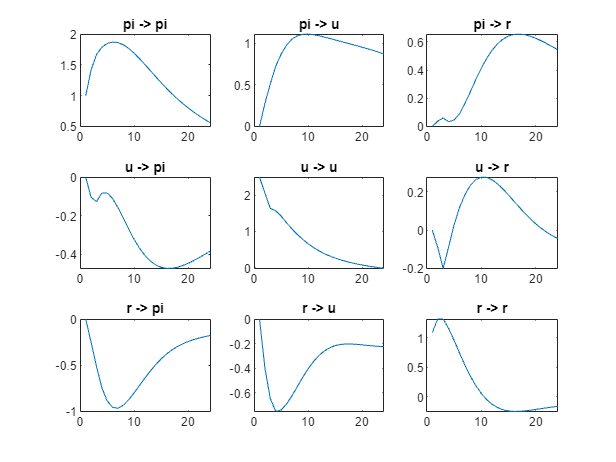

t = tiledlayout(3, 3);
names = ["pi", "u", "r"];
s2 = diag(EstMdlF.Covariance);
for i = 1 : 3
    for j = 1 : 3

        ax = nexttile(t);
        plot(ax, Response(:,i,j) ./ sqrt(s2(1)));
        title(names(i) + " -> " + names(j))

    end
end

#### Computing IRF intervals by Monte Carlo

First, we can simulate many posterior draws of VAR coefficients and the covariance matrix. For each draw, we construct a VARM model and compute the impulse response functions. Repeat the process for all draws, we obtain a collection of impulse response functions. After sorting them we can compute the quantiles (say 5% and 95%), which constitute a band that characterizes the uncertainties on the impulse response functions. Example code:

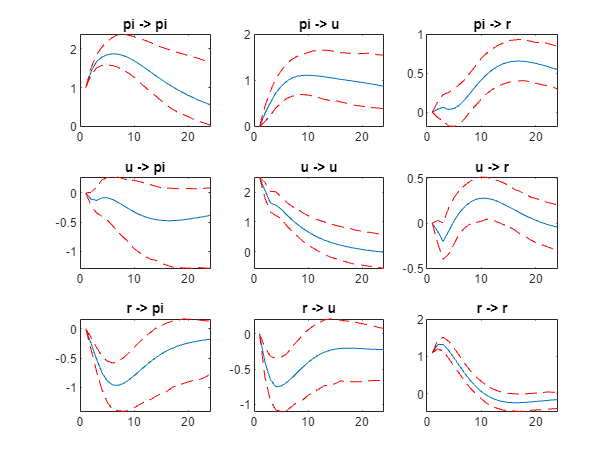

numDraws = 500;
if isa(EstMdl, 'empiricalbvarm')
    draws = randsample(10000,numDraws);
    Coeff = EstMdl.CoeffDraws(:, draws);
    Sigma = EstMdl.SigmaDraws(:, :, draws);
else
    [Coeff,Sigma] = simulate(EstMdl,'NumDraws',numDraws);
end
Response4D = zeros(24,3,3,numDraws);
for m = 1:numDraws
    A = reshape(Coeff(:,m),13,3)';
    mdl = varm('Constant',A(:,13),'AR',{A(:,1:3),A(:,4:6),A(:,7:9),A(:,10:12)},'Covariance',Sigma(:,:,m));
    Response4D(:,:,:,m) = irf(mdl,'NumObs',24);
end
Response05 = quantile(Response4D,0.05,4);
Response95 = quantile(Response4D,0.95,4);
t = tiledlayout(3, 3);
names = ["pi", "u", "r"];
for i = 1 : 3
    for j = 1 : 3

        ax = nexttile();
        plot(ax, Response(:,i,j) ./ sqrt(s2(1)));
        title(names(i) + " -> " + names(j))
        hold on
        plot(ax, Response05(:,i,j) ./ sqrt(s2(1)), 'r--')
        plot(ax, Response95(:,i,j) ./ sqrt(s2(1)), 'r--')
        hold off

    end
end

# Other resources

[BEAR toolbox](https://github.com/european-central-bank/BEAR-toolbox)

The Bayesian Estimation, Analysis and Regression toolbox (BEAR) is a comprehensive (Bayesian Panel) VAR toolbox for forecasting and policy analysis.

BEAR is a MATLAB based toolbox which is easy for non-technical users to understand, augment and adapt. In particular, BEAR includes a user-friendly graphical interface which allows the tool to be used by country desk economists.

Furthermore, BEAR is well documented, both within the code as well as including a detailed theoretical and user’s guide. BEAR includes state-of-the art applications such as FAVARs, stochastic volatility, time-varying parameters, mixed-frequency, sign and magnitude restrictions, conditional forecasts, Bayesian forecast evaluation measures, Bayesian Panel VAR using different prior distributions (for example hierarchical priors).

BEAR is specifically developed for transparently supplying a tool for state-of-the-art research and is planned to be further developed to always be at the frontier of economic research.

Use of BEAR implies acceptance of the End User [Licence Agreement (EULA)](https://github.com/european-central-bank/BEAR-toolbox#License) for the Use of the Software “the Bayesian Estimation, Analysis and Regression (BEAR) toolbox”.

[Dynare](https://www.dynare.org/)

Dynare is a software platform for handling a wide class of economic models, in particular dynamic stochastic general equilibrium (DSGE) and overlapping generations (OLG) models. The models solved by Dynare include those relying on the rational expectations hypothesis, wherein agents form their expectations about the future in a way consistent with the model. But Dynare is also able to handle models where expectations are formed differently: on one extreme, models where agents perfectly anticipate the future; on the other extreme, models where agents have limited rationality or imperfect knowledge of the state of the economy and, hence, form their expectations through a learning process. In terms of types of agents, models solved by Dynare can incorporate consumers, productive firms, governments, monetary authorities, investors and financial intermediaries. Some degree of heterogeneity can be achieved by including several distinct classes of agents in each of the aforementioned agent categories.

Dynare offers a user-friendly and intuitive way of describing these models. It is able to perform simulations of the model given a calibration of the model parameters and is also able to estimate these parameters given a dataset. In practice, the user will write a text file containing the list of model variables, the dynamic equations linking these variables together, the computing tasks to be performed and the desired graphical or numerical outputs.

A large panel of applied mathematics and computer science techniques are internally employed by Dynare: multivariate nonlinear solving and optimization, matrix factorizations, local functional approximation, Kalman filters and smoothers, MCMC techniques for Bayesian estimation, graph algorithms, optimal control, etc. References to the literature can be found [here](https://www.dynare.org/bibliography).

**SAMNet is a repository of models for modelling and forecasting the economy**

web('https://samnet.org.za/model-databases/','browser')

edit SamNet.mod

Starting Dynare (version 5.3).
Calling Dynare with arguments: none
Starting preprocessing of the model file ...
Found 19 equation(s).
Evaluating expressions...done
Computing static model derivatives (order 1).
Computing dynamic model derivatives (order 1).
Processing outputs ...
done
Preprocessing completed.


STEADY-STATE RESULTS:

C      		 0.31994
C_h    		 0.2941
C_e    		 0.0216553
C_b    		 0.00418431
H_h    		 0.748768
H_e    		 0.251232
N      		 0.32865
W      		 0.876146
q      		 4.36421
D      		 0.677659
L_e    		 0.757161
R_d    		 1.00908
R_l    		 1.01365
Sprd   		 0.00457273
Y      		 0.31994
kappa  		 0.105
A      		 1
Z      		 1
vareps 		 0

EIGENVALUES:
         Modulus             Real        Imaginary

       1.903e-09       -1.903e-09                0
       1.903e-09        1.903e-09                0
       1.559e-08        1.559e-08                0
       1.559e-08       -1.559e-08                0
          0.5877           0.5877                0
          

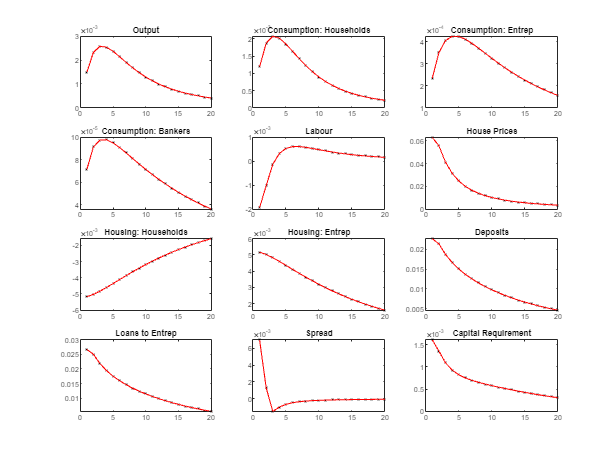

Total computing time : 0h00m05s


dynare SamNet.mod

[IRIS toolbox](https://iris.igpmn.org/)

IRIS is a free, open-source toolbox for macroeconomic modeling and forecasting in Matlab®, originally developed by the IRIS Solutions Team and currently maintained and supported by the Global Projection Model Network.

In a user-friendly command-oriented environment, IRIS integrates core modeling functions (including a flexible model file language with a powerful preparser, a variety of tools for simulation, estimation, forecasting and model diagnostics, practical techniques for judgmental adjustments, and more) with supporting infrastructure (such as data management, time series analysis, and reporting).

# References

[1] Cogley, T. and Sargent, T. (2005). **Drifts and volatilities: Monetary policies and outcomes in the post WWII** U.S, Review of Economic Dynamics, 8, 262-302.

[2] Primiceri. G., (2005). **Time varying structural vector autoregressions and monetary policy**, Review of Economic Studies, 72, 821-852.

[3] Koop, G. and Korobilis, D. (2009). **Bayesian Multivariate Time Series Methods for Empirical Macroeconomics**, Working Paper series 47-09, Rimini Centre for Economic Analysis.